# **Question 1**

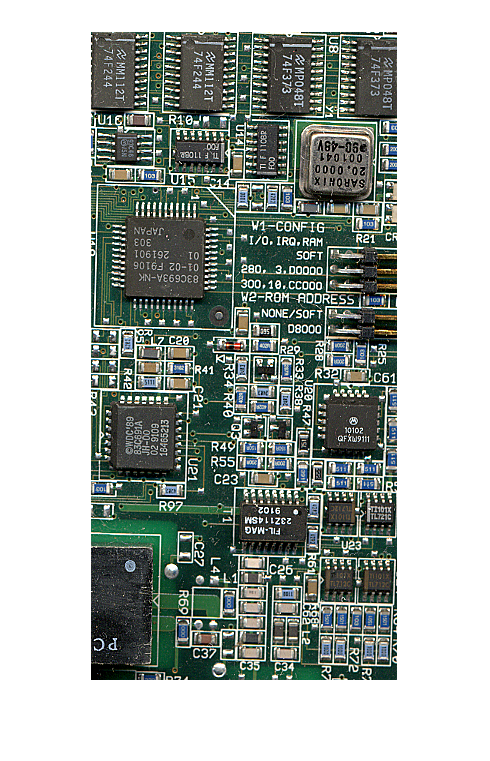

Img = imread('board.tif');
imshow(Img);

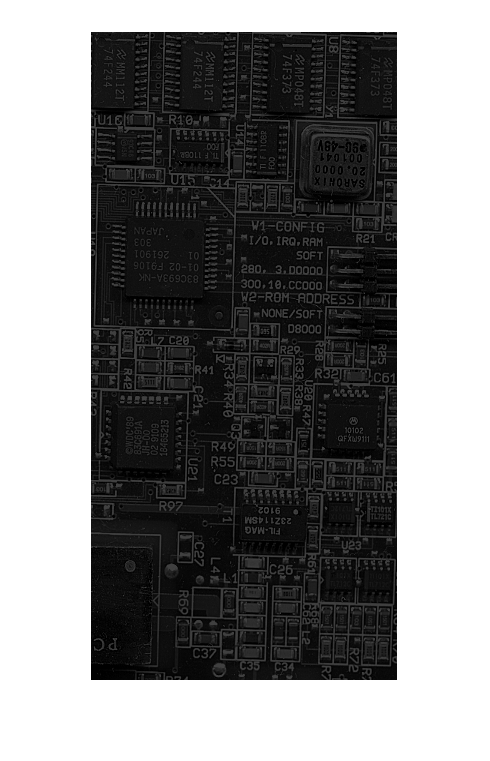

% Part A, show 25% gray image
GrayImg = rgb2gray(Img);
GrayAdjust = GrayImg*0.25;
imshow(GrayAdjust);

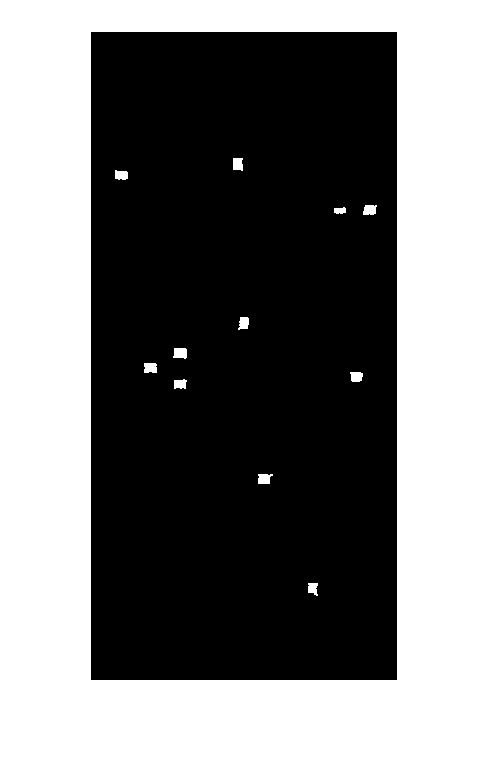

% Part B, Create mask for baige
[BW, MskImage] = createMask(Img);
BinaryMask = bwareaopen(BW,20);             % remove white noise
se = strel('square',2);                     
BinaryMask = imdilate(BinaryMask,se);       % fill in the white ones fully
imshow(BinaryMask);

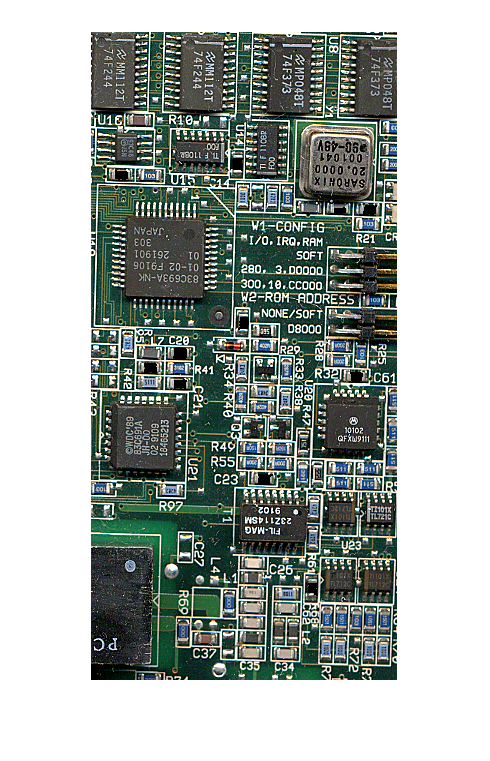

% apply mask
MaskedRGBImage = bsxfun(@times,Img,cast(~BinaryMask,'like',Img));
imshow(MaskedRGBImage);

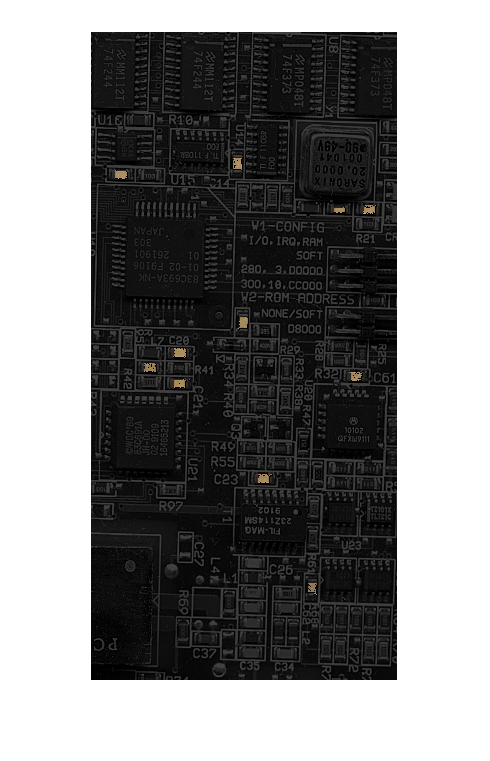

% Part C, combine parts A and B
imshow(GrayAdjust);
hold on;
h = imshow(MskImage);
hold off;
set(h, 'AlphaData', BinaryMask);

# **Question 2**

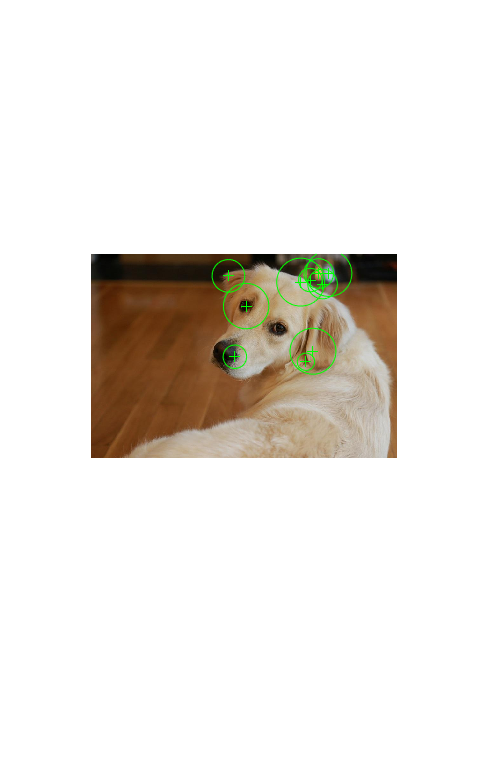

% Part A, Surf
Sherlock = imread('sherlock.jpg');
GraySherlock = rgb2gray(Sherlock);
points1 = detectSURFFeatures(GraySherlock);
imshow(Sherlock); 
hold on;
a=plot(points1.selectStrongest(10));
hold off;

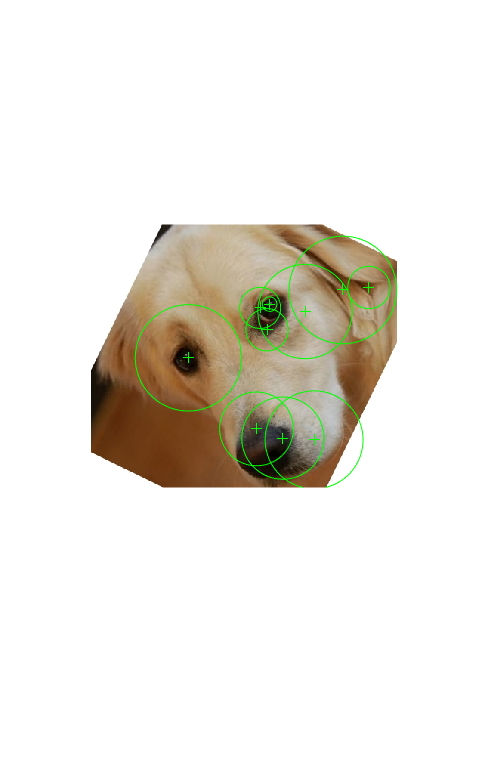

% Part B
TiltedSherlock = imread('zEXAMPLE.jpg');
GrayTiltSherlock = rgb2gray(TiltedSherlock);
points2 = detectSURFFeatures(GrayTiltSherlock);
imshow(TiltedSherlock); 
hold on;
b=plot(points2.selectStrongest(10));
hold off;

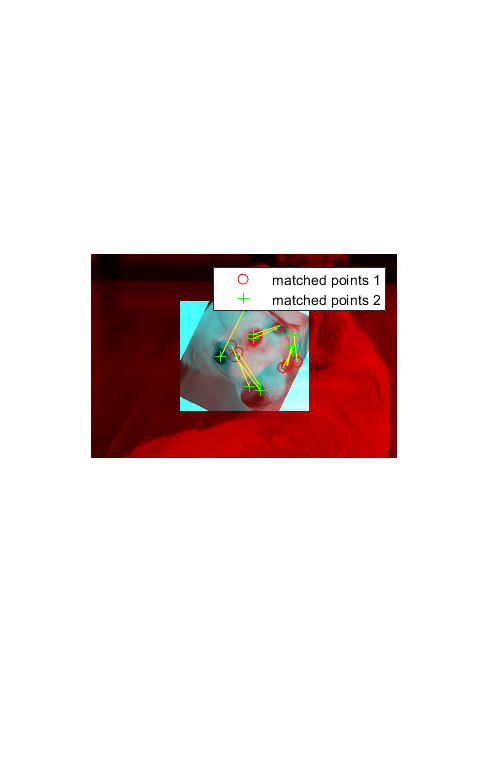


% Visualising matched features
[f1,vpts1] = extractFeatures(GraySherlock,points1); % f1 is features 1, vpts1 is valid points 1
[f2,vpts2] = extractFeatures(GrayTiltSherlock,points2);
% Retrieve the locations of the matched points
indexPairs = matchFeatures(f1,f2) ;
matchedPoints1 = vpts1(indexPairs(:,1));
matchedPoints2 = vpts2(indexPairs(:,2));
% Display the matching points
showMatchedFeatures(Sherlock,TiltedSherlock,...
    matchedPoints1,matchedPoints2);
legend('matched points 1','matched points 2');

% Part C, Calculate how much it's rotated by
[tform, inlierDistorted, inlierOriginal] = estimateGeometricTransform(...
    matchedPoints2, matchedPoints1, 'similarity');
Tinv  = tform.invert.T;

ss = Tinv(2,1);
sc = Tinv(1,1);
scale_recovered = sqrt(ss*ss + sc*sc)

scale_recovered = single
0.9947

theta_recovered = atan2(ss,sc)*180/pi

theta_recovered = single
63.9065

# Question 3

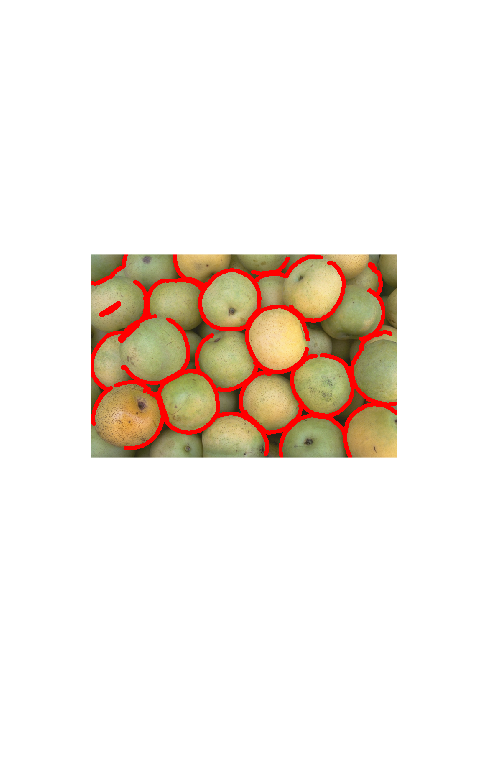

% Part A
Pears = imread('pears.png');
BWPears = rgb2gray(Pears);
BW1 = edge(BWPears,'canny', 0.3);
BW1 = bwareaopen(BW1,90);             % remove white noise
BW1 = imdilate(BW1, strel('disk',5)); % make line thicker
imshow(Pears);
hold on;
RedBorder = imshow(BW1, 'ColorMap', [0 0 0; 1 0 0]);
hold off;
set(RedBorder, 'AlphaData', BW1);

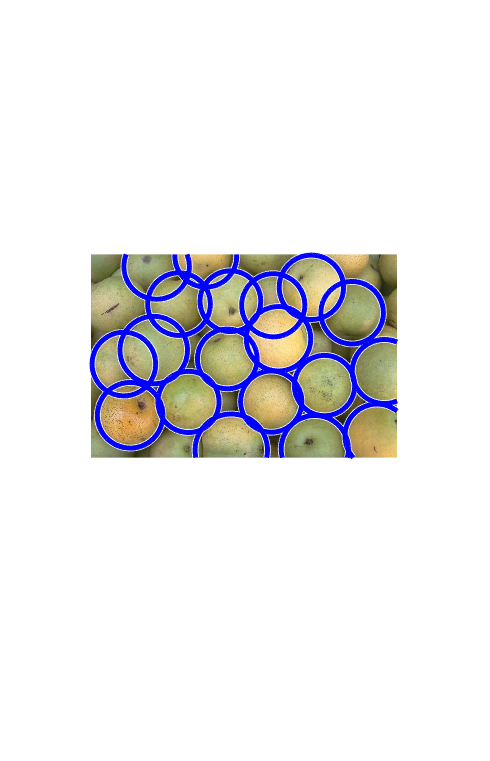


% Part B
imshow(Pears);
[centers, radii] = imfindcircles(BWPears,[70 90], 'ObjectPolarity', 'bright', ...
    'Sensitivity',0.98);
viscircles(centers, radii,'color','b', 'LineWidth', 3);

function [BW,maskedRGBImage] = createMask(RGB)
%createMask  Threshold RGB image using auto-generated code from colorThresholder app.
%  [BW,MASKEDRGBIMAGE] = createMask(RGB) thresholds image RGB using
%  auto-generated code from the colorThresholder app. The colorspace and
%  range for each channel of the colorspace were set within the app. The
%  segmentation mask is returned in BW, and a composite of the mask and
%  original RGB images is returned in maskedRGBImage.

% Auto-generated by colorThresholder app on 18-Jun-2019
%------------------------------------------------------


% Convert RGB image to chosen color space
I = rgb2hsv(RGB);

% Define thresholds for channel 1 based on histogram settings
channel1Min = 0.000;
channel1Max = 0.139;

% Define thresholds for channel 2 based on histogram settings
channel2Min = 0.322;
channel2Max = 0.639;

% Define thresholds for channel 3 based on histogram settings
channel3Min = 0.558;
channel3Max = 0.742;

% Create mask based on chosen histogram thresholds
sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
    (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
    (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;

% Initialize output masked image based on input image.
maskedRGBImage = RGB;

% Set background pixels where BW is false to zero.
maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end
